clc
clear all

load("result/theta_throughput_vs_N.mat")
load("result/gamma_throughput_vs_N.mat")

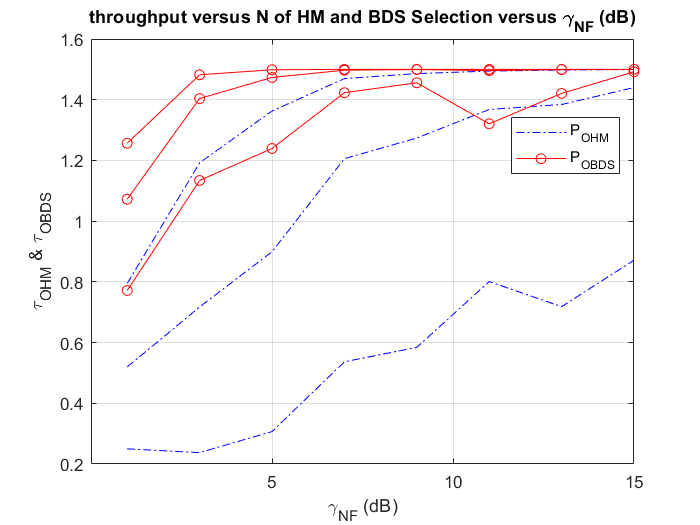

gamma_NF_db = [5:30];
gamma_NF = 10.^(gamma_NF_db/10);

figure
plot([1:2:15], gamma_throughput_vs_N, '-.b');
hold on
plot([1:2:15], theta_throughput_vs_N, '-or');

legend({'P_{OHM}', '', '', 'P_{OBDS}'}, 'Location', 'best')


xlabel('\gamma_{NF} (dB)'); ylabel('\tau_{OHM} & \tau_{OBDS}');
title('throughput versus N of HM and BDS Selection versus \gamma_{NF} (dB)')
grid on, hold on
% ylim([1e-4 1])
% xlim([1 15])
xticks(5:5:30)


% annotation('textarrow', [0.5,0.3], [0.4,0.7], 'String', 'N = 1,2,3,4', 'LineWidth', 0.1);